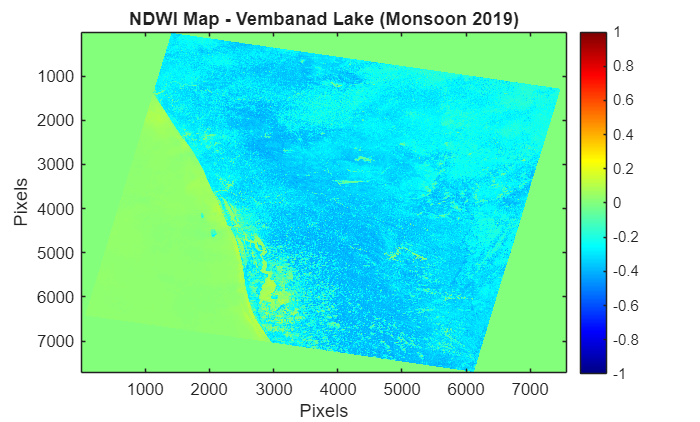

%% ☔ NDWI CALCULATION FOR MONSOON SCENES (e.g., Monsoon 2019)

% 🔁 Clear workspace and command window
clc;
clear;

%% ✅ Step 1: Set File Paths for Monsoon Scene
% Replace these with the full or relative path to your Landsat monsoon images

green_band_file = 'C:\Users\91998\MATLAB Drive\proooo\2019-20\LC08_L2SP_144053_20190601_20200828_02_T1_SR_B3.TIF';  % Band 3 (Green)
nir_band_file   = 'C:\Users\91998\MATLAB Drive\proooo\2019-20\LC08_L2SP_144053_20190601_20200828_02_T1_SR_B5.TIF';  % Band 5 (NIR)

%% ✅ Step 2: Load Bands Using readgeoraster
[green, R] = readgeoraster(green_band_file);  % Spatial reference info R
nir = readgeoraster(nir_band_file);

% Convert to double for calculation
green = double(green);
nir = double(nir);

%% ✅ Step 3: Compute NDWI
ndwi = (green - nir) ./ (green + nir + eps);  % eps avoids division by zero


ndwi_2019_monsoon = ndwi;
save('ndwi_2019_monsoon.mat', 'ndwi_2019_monsoon');

%% ✅ Step 4: Display NDWI Map
figure;
imagesc(ndwi, [-1, 1]);  % Typical NDWI range
colormap('jet');
colorbar;
title('NDWI Map - Vembanad Lake (Monsoon 2019)');
xlabel('Pixels');
ylabel('Pixels');

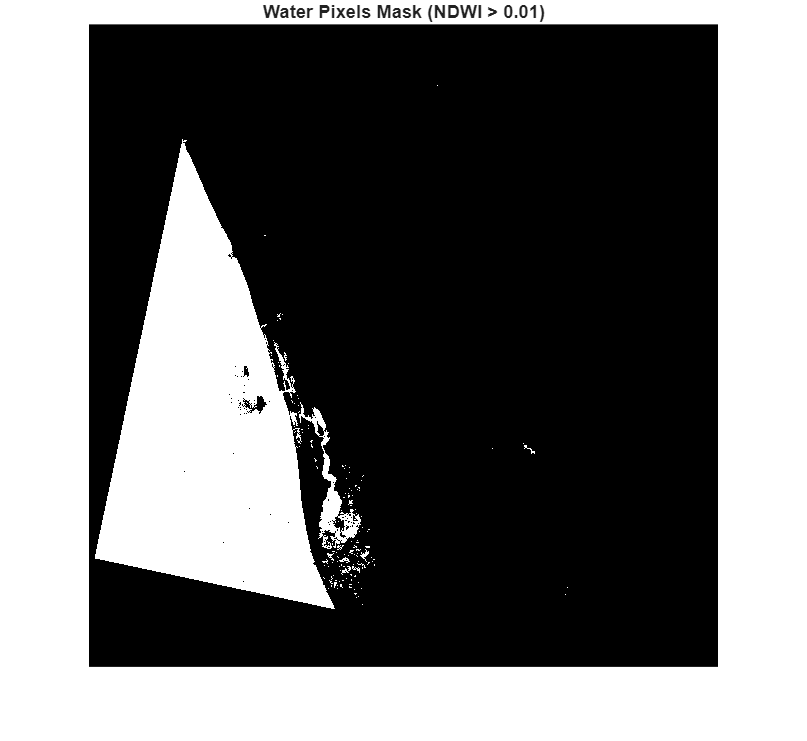


%% ✅ Step 5: Generate Water Mask from NDWI
% Adjust threshold if needed (e.g., 0.2 → 0.05 → 0.0)
water_mask = ndwi > 0.01;

% Display water mask as binary image
figure;
imshow(water_mask);
title('Water Pixels Mask (NDWI > 0.01)');


%% ✅ Step 6: Estimate Wetland Area (in sq.km)
% Each pixel = 30m × 30m = 900 m² = 0.0009 km²
num_water_pixels = sum(water_mask(:));
wetland_area_km2 = num_water_pixels * 0.0009;

fprintf('✅ Estimated Wetland Area (Monsoon 2019): %.2f sq.km\n', wetland_area_km2);

✅ Estimated Wetland Area (Monsoon 2019): 7702.62 sq.km


wetland_2019_summer = wetland_area_km2;

%% ✅ Step 7: Save Outputs for Later Comparison
% Save NDWI image (normalized to 0–1)
ndwi_image = mat2gray(ndwi);
imwrite(ndwi_image, 'NDWI_2019_Monsoon.png');

% Save water mask
imwrite(water_mask, 'WaterMask_2019_Monsoon.png');
save('NDWI_2019_Monsoon.mat', 'ndwi');

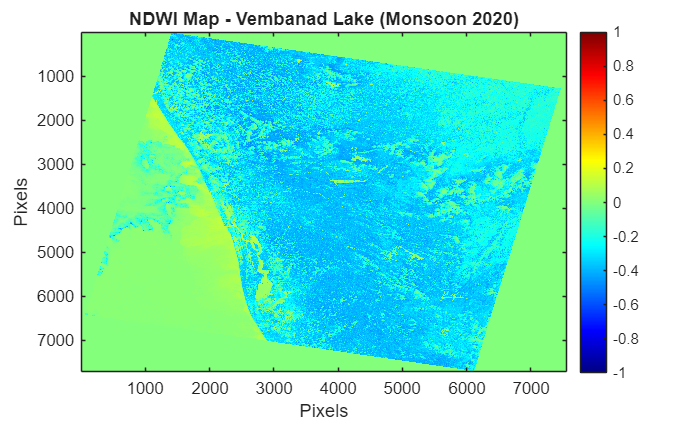

%% ☔ NDWI CALCULATION FOR MONSOON SCENES (e.g., Monsoon 2020)

% 🔁 Clear workspace and command window
clc;
clear;

%% ✅ Step 1: Set File Paths for Monsoon Scene
% Replace these with the full or relative path to your Landsat monsoon images

green_band_file = 'C:\Users\91998\MATLAB Drive\proooo\2020\LC08_L2SP_144053_20200721_20200911_02_T1_SR_B3.TIF';  % Band 3 (Green)
nir_band_file   = 'C:\Users\91998\MATLAB Drive\proooo\2020\LC08_L2SP_144053_20200721_20200911_02_T1_SR_B5.TIF';  % Band 5 (NIR)

%% ✅ Step 2: Load Bands Using readgeoraster
[green, R] = readgeoraster(green_band_file);  % Spatial reference info R
nir = readgeoraster(nir_band_file);

% Convert to double for calculation
green = double(green);
nir = double(nir);

%% ✅ Step 3: Compute NDWI
ndwi = (green - nir) ./ (green + nir + eps);  % eps avoids division by zero

% figure;
% histogram(ndwi(:), 50);
% title('NDWI Histogram - Monsoon 2020');
% xlabel('NDWI Value');
% ylabel('Pixel Count');

ndwi_2020_monsoon = ndwi;
save('ndwi_2020_monsoon.mat', 'ndwi_2020_monsoon');

%% ✅ Step 4: Display NDWI Map
figure;
imagesc(ndwi, [-1, 1]);  % Typical NDWI range
colormap('jet');
colorbar;
title('NDWI Map - Vembanad Lake (Monsoon 2020)');
xlabel('Pixels');
ylabel('Pixels');

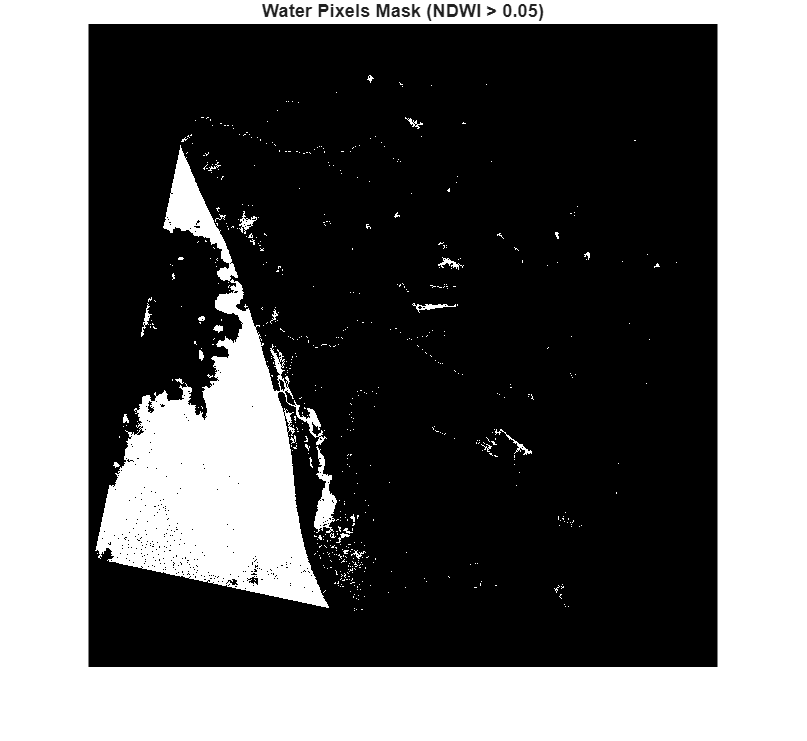


%% ✅ Step 5: Generate Water Mask from NDWI
% Adjust threshold if needed (e.g., 0.2 → 0.05 → 0.0)
water_mask = ndwi > 0.01;

% Display water mask as binary image
figure;
imshow(water_mask);
title('Water Pixels Mask (NDWI > 0.05)');


%% ✅ Step 6: Estimate Wetland Area (in sq.km)
% Each pixel = 30m × 30m = 900 m² = 0.0009 km²
num_water_pixels = sum(water_mask(:));
wetland_area_km2 = num_water_pixels * 0.0009;

fprintf('✅ Estimated Wetland Area (Monsoon 2020): %.2f sq.km\n', wetland_area_km2);

✅ Estimated Wetland Area (Monsoon 2020): 5724.90 sq.km


wetland_2020_summer = wetland_area_km2;

%% ✅ Step 7: Save Outputs for Later Comparison
% Save NDWI image (normalized to 0–1)
ndwi_image = mat2gray(ndwi);
imwrite(ndwi_image, 'NDWI_2020_Monsoon.png');

% Save water mask
imwrite(water_mask, 'WaterMask_2020_Monsoon.png');
save('NDWI_2020_Monsoon.mat', 'ndwi');

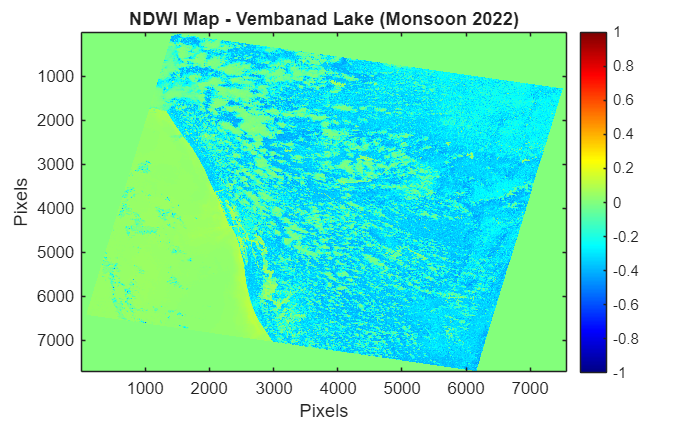

%% ☔ NDWI CALCULATION FOR MONSOON SCENES (e.g., Monsoon 2022)

% 🔁 Clear workspace and command window
clc;
clear;

%% ✅ Step 1: Set File Paths for Monsoon Scene
% Replace these with the full or relative path to your Landsat monsoon images

green_band_file = 'C:\Users\91998\MATLAB Drive\proooo\2022-23\LC09_L2SP_144053_20220921_20230328_02_T1_SR_B3.TIF';  % Band 3 (Green)
nir_band_file   = 'C:\Users\91998\MATLAB Drive\proooo\2022-23\LC09_L2SP_144053_20220921_20230328_02_T1_SR_B5.TIF';  % Band 5 (NIR)

%% ✅ Step 2: Load Bands Using readgeoraster
[green, R] = readgeoraster(green_band_file);  % Spatial reference info R
nir = readgeoraster(nir_band_file);

% Convert to double for calculation
green = double(green);
nir = double(nir);

%% ✅ Step 3: Compute NDWI
ndwi = (green - nir) ./ (green + nir + eps);% eps avoids division by zero

% figure;
% histogram(ndwi(:), 50);
% title('NDWI Histogram - Monsoon 2022');
% xlabel('NDWI Value');
% ylabel('Pixel Count');




ndwi_2022_monsoon = ndwi;
save('ndwi_2022_monsoon.mat', 'ndwi_2022_monsoon');

%% ✅ Step 4: Display NDWI Map
figure;
imagesc(ndwi, [-1, 1]);  % Typical NDWI range
colormap('jet');
colorbar;
title('NDWI Map - Vembanad Lake (Monsoon 2022)');
xlabel('Pixels');
ylabel('Pixels');

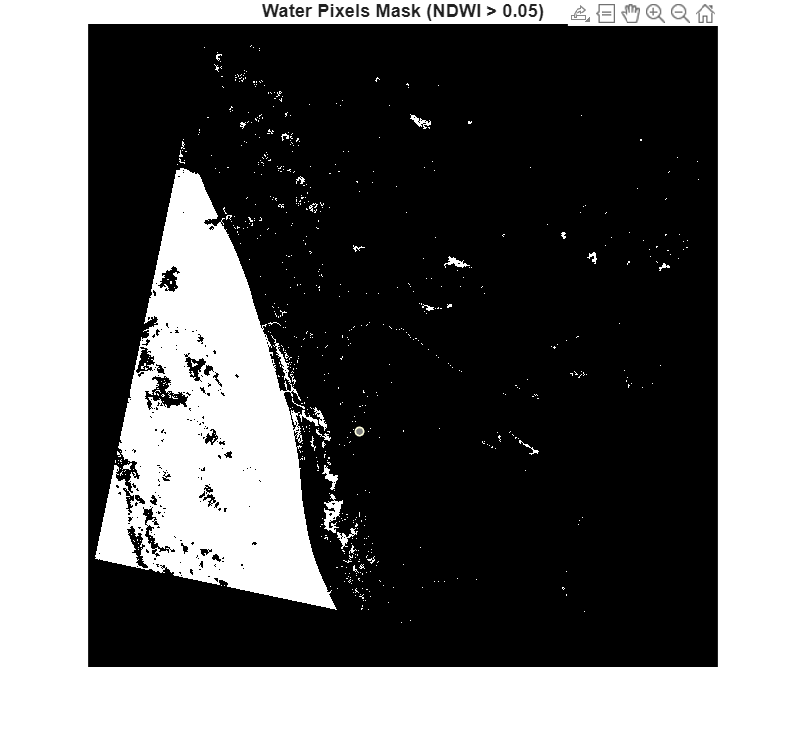


%% ✅ Step 5: Generate Water Mask from NDWI
% Adjust threshold if needed (e.g., 0.2 → 0.05 → 0.0)
water_mask = ndwi > 0.01;

% Display water mask as binary image
figure;
imshow(water_mask);
title('Water Pixels Mask (NDWI > 0.05)');


%% ✅ Step 6: Estimate Wetland Area (in sq.km)
% Each pixel = 30m × 30m = 900 m² = 0.0009 km²
num_water_pixels = sum(water_mask(:));
wetland_area_km2 = num_water_pixels * 0.0009;

fprintf('✅ Estimated Wetland Area (Monsoon 2022): %.2f sq.km\n', wetland_area_km2);

✅ Estimated Wetland Area (Monsoon 2022): 7290.86 sq.km


wetland_2022_summer = wetland_area_km2;

%% ✅ Step 7: Save Outputs for Later Comparison
% Save NDWI image (normalized to 0–1)
ndwi_image = mat2gray(ndwi);
imwrite(ndwi_image, 'NDWI_2022_Monsoon.png');

% Save water mask
imwrite(water_mask, 'WaterMask_2022_Monsoon.png');
save('NDWI_2022_Monsoon.mat', 'ndwi');

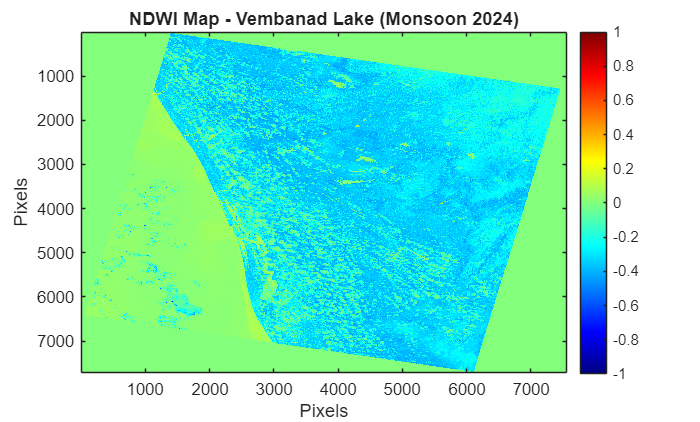

%% ☔ NDWI CALCULATION FOR MONSOON SCENES (e.g., Monsoon 2024)

% 🔁 Clear workspace and command window
clc;
clear;

%% ✅ Step 1: Set File Paths for Monsoon Scene
% Replace these with the full or relative path to your Landsat monsoon images

green_band_file = 'C:\Users\91998\MATLAB Drive\proooo\2024\LC08_L2SP_144053_20240918_20240923_02_T1_SR_B3.TIF';  % Band 3 (Green)
nir_band_file   = 'C:\Users\91998\MATLAB Drive\proooo\2024\LC08_L2SP_144053_20240918_20240923_02_T1_SR_B5.TIF';  % Band 5 (NIR)

%% ✅ Step 2: Load Bands Using readgeoraster
[green, R] = readgeoraster(green_band_file);  % Spatial reference info R
nir = readgeoraster(nir_band_file);

% Convert to double for calculation
green = double(green);
nir = double(nir);

%% ✅ Step 3: Compute NDWI
ndwi = (green - nir) ./ (green + nir + eps);  % eps avoids division by zero

% figure;
% histogram(ndwi(:), 50);
% title('NDWI Histogram - Monsoon 2024');
% xlabel('NDWI Value');
% ylabel('Pixel Count');

ndwi_2024_monsoon = ndwi;
save('ndwi_2024_monsoon.mat', 'ndwi_2024_monsoon');

%% ✅ Step 4: Display NDWI Map
figure;
imagesc(ndwi, [-1, 1]);  % Typical NDWI range
colormap('jet');
colorbar;
title('NDWI Map - Vembanad Lake (Monsoon 2024)');
xlabel('Pixels');
ylabel('Pixels');

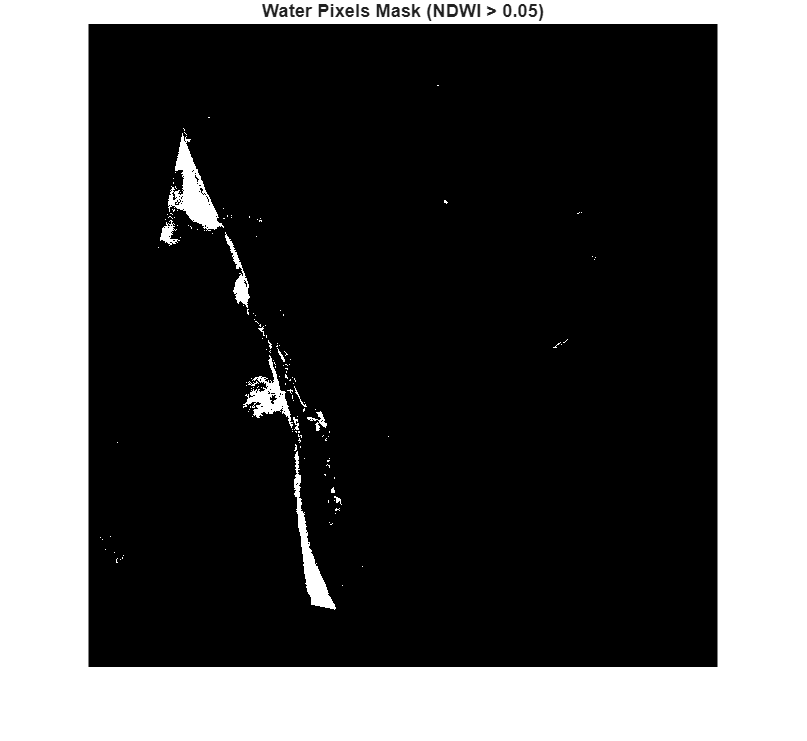


%% ✅ Step 5: Generate Water Mask from NDWI
% Adjust threshold if needed (e.g., 0.2 → 0.05 → 0.0)
water_mask = ndwi > 0.05;

% Display water mask as binary image
figure;
imshow(water_mask);
title('Water Pixels Mask (NDWI > 0.05)');


%% ✅ Step 6: Estimate Wetland Area (in sq.km)
% Each pixel = 30m × 30m = 900 m² = 0.0009 km²
num_water_pixels = sum(water_mask(:));
wetland_area_km2 = num_water_pixels * 0.0009;

fprintf('✅ Estimated Wetland Area (Monsoon 2024): %.2f sq.km\n', wetland_area_km2);

✅ Estimated Wetland Area (Monsoon 2024): 778.19 sq.km


wetland_2024_summer = wetland_area_km2;

%% ✅ Step 7: Save Outputs for Later Comparison
% Save NDWI image (normalized to 0–1)
ndwi_image = mat2gray(ndwi);
imwrite(ndwi_image, 'NDWI_2024_Monsoon.png');

% Save water mask
imwrite(water_mask, 'WaterMask_2024_Monsoon.png');
save('NDWI_2024_Monsoon.mat', 'ndwi');